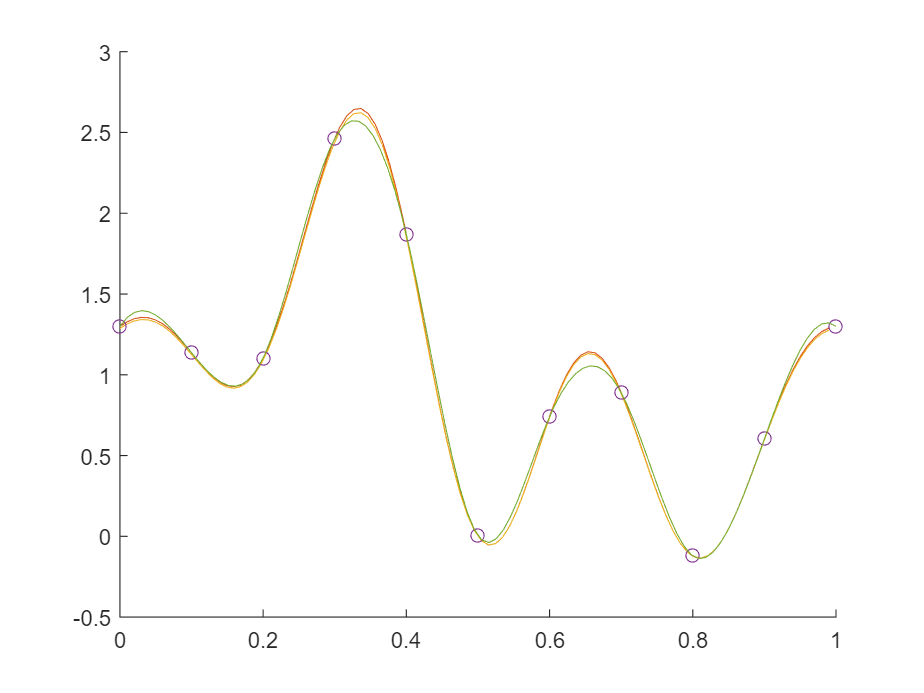

close all
clear all

% Signal
N = 100;
tmax = 1;
dt = tmax/(N+1);
t = 0:dt:dt*N;
y = (1+(sin(2*pi*t)+cos(6*pi*t)).*exp(-(t-0.5).^2/0.2));

% FFT
P = tmax;
omega = 2*pi/P;
F = fft(y);

% Fourier series coefficients
a0 = real(F(1))/N;
b0 = 0;
Nterms = round(N/2);
FHalf = F(2:Nterms);
a = [a0,2/N*real(FHalf)];
b = [b0,-2/N*imag(FHalf)];

% Compute the fourier series
omegatn = t*omega.*(0:Nterms-1)';
fbcos = cos(omegatn);
fbsin = sin(omegatn);
fseries = a*fbcos + b*fbsin;

% Collect points from fourier series
tp = 0:0.1:1;
yp = interp1([t,t+tmax],[fseries,fseries],tp);
ts = linspace(0,tmax,N);
ys = spline(tp,yp,ts);


figure
hold on
plot(t,y)
plot(t,fseries)
plot(t,ifft(F))
plot(tp,yp,'o')
plot(ts,ys)
hold off

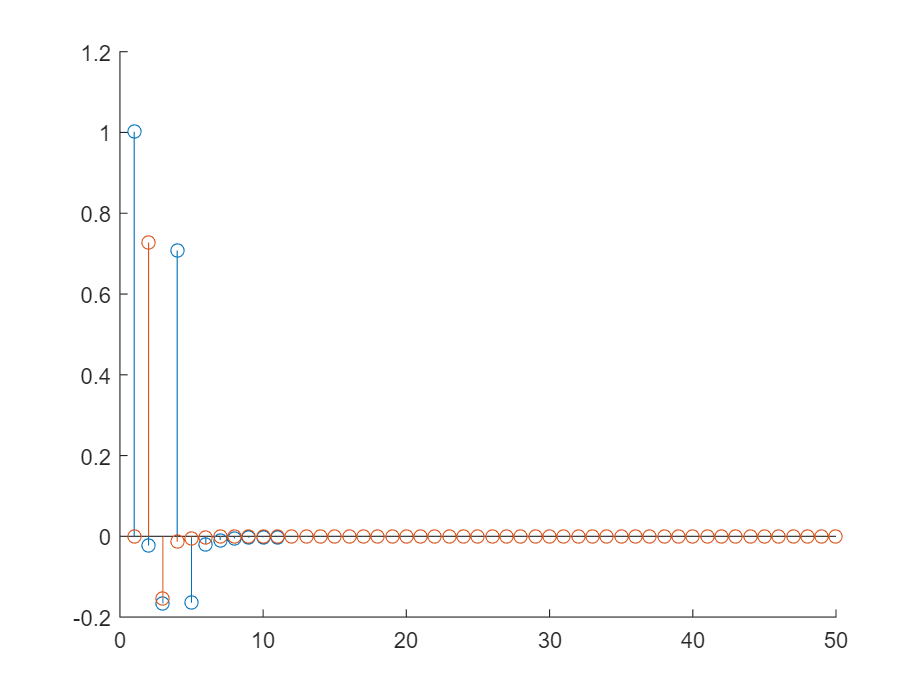

figure
hold on
stem(a)
stem(b)